a= randi ([-20,20],2,3,4)

a = a(:,:,1) =

   -18   -19     1
     7   -18   -17


a(:,:,2) =

    13     9     7
    13   -14     1


a(:,:,3) =

    19    12    -3
     6    -2    13


a(:,:,4) =

   -17   -13    14
   -15    -4    12


[m,n,o]=size(a)

m = 2

n = 3

o = 4

colors= ["y","m","c","r","g","b","w","k"]

colors = 1×8 string array
    "y"    "m"    "c"    "r"    "g"    "b"    "w"    "k"


amin=min(a,[],'all')

amin = -19

amax=max(a,[],'all')

amax = 19

y1 = 249.5000

y2 = 75.6554

y2 = 75.6600

y1 = 57

y2 = 55.8438

y2 = 55.8400

y1 = 112.5000

y2 = 54.9301

y2 = 54.9300

y1 = 116.5000

y2 = 84.1990

y2 = 84.2000

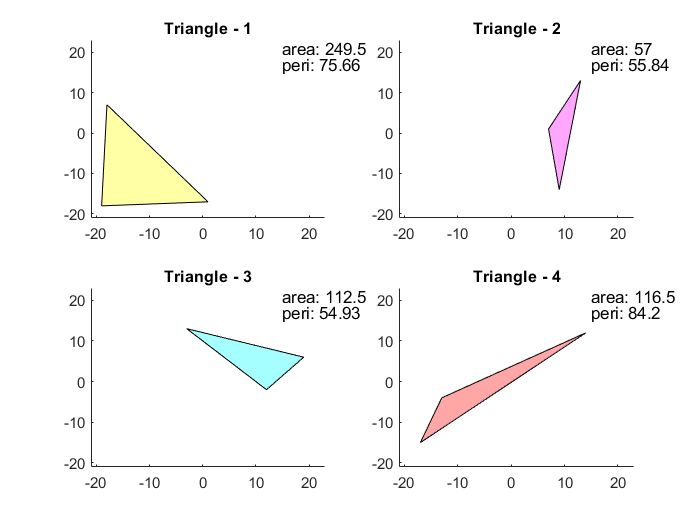

for i=1:o
    x=a(1,:,i);
    y=a(2,:,i);
    p=polyshape(x,y);
    
    y1=area(p)
    y2=perimeter(p)
    y2=round(y2,2)
    
    subplot(ceil(o/2),2,i)
    plot(p,'FaceColor',colors(i))
    axis([amin-2,amax+4,amin-2,amax+4])
    title(append('Triangle - ',num2str(i)))
    
    text(amax-4,amax+2,append('area: ',num2str(y1)))
    text(amax-4,amax-2,append('peri: ',num2str(y2)))
    
end